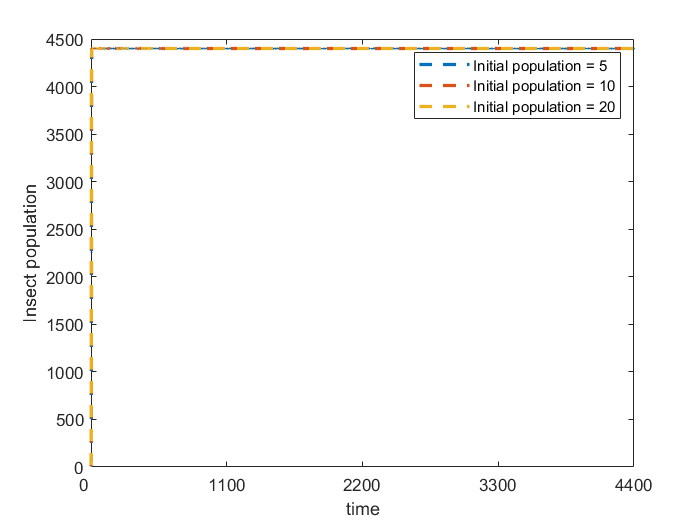

clc; clear all; close all
K = 4400;
I_0 = [5; 10; 20];
[t, I] = ode45(@(t, I) fun(t, I, K),[0 K], I_0 );
plot(t, I,'--','LineWidth', 2);
xlabel('time'); ylabel('Insect population')
legend('Initial population = 5', 'Initial population = 10', 'Initial population = 20')
set(gca, 'XLim', [0, K], 'XTick', 0:1100:K,...
    'XTickLabel', 0:1100:K);

function dI = fun(t, I, K)
r = 2;
%b = 2000;
%a = 550;
positive_term = r*I.*(1 - I./K);
%negative_term = b*(I^2 / (a^2 + I^2));
dI = positive_term; % - negative_term;
end